%chebyshew filter
clc;
clear all;
close all;

[inputSignal, Fs] = audioread('Goutami.wav');
T = 1 / Fs;             % Sampling period
t = 0:T:1;              % Time vector

% Define filter parameters
Kp = -5; 
Ks = -30; 
Fp = 3000; 
Fs = 3500;
Ts=1;

%if frequency is given
wp=2*pi*Fp

wp = 1.8850e+04

ws=2*pi*Fs

ws = 2.1991e+04

sigpp=(2/Ts)*tan(wp/2); 
sigss=(2/Ts)*tan(ws/2);


% Calculate normalized frequencies
sigp = sigpp / sigpp;
sigs = sigss / sigpp;

% Calculate epsilon
e=sqrt(10^(-2*Kp/20)-1) %epslon

e = 1.4705


% Calculate attenuation parameters
del_p=1-(1/sqrt(1+1*e^2))

del_p = 0.4377

del_s =10^(Ks/20) 

del_s = 0.0316


% Calculate filter order
K = sigp / sigs;
d = sqrt((((1-del_p)^-2)-1)/((del_s^-2)-1))

d = 0.0465

N = acosh(1/d) / acosh(1/K)

N = 3.2225

n=ceil(N)

n = 4


a=1/2*((((1+sqrt(1+e^2))/e)^(1/3))-((1+sqrt(1+e^2))/e)^(-1/3))

a = 0.2137

b=1/2*((((1+sqrt(1+e^2))/e)^(1/3))+((1+sqrt(1+e^2))/e)^(-1/3))

b = 1.0226

poles=zeros(1,n);
for l=1:n
    sig_k=-a*sin(((2*l-1)*pi)/6)%sigma k
    disp(sig_k);
    omg_k=b*cos(((2*l-1)*pi)/6)%omega k
    disp((omg_k));
    poles(l)=sig_k+(omg_k)*i;
    display(poles);
end

sig_k = -0.1068

   -0.1068



omg_k = 0.8856

    0.8856



poles =   -0.1068 + 0.8856i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


sig_k = -0.2137

   -0.2137



omg_k = 6.2615e-17

   6.2615e-17



poles =   -0.1068 + 0.8856i  -0.2137 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


sig_k = -0.1068

   -0.1068



omg_k = -0.8856

   -0.8856



poles =   -0.1068 + 0.8856i  -0.2137 + 0.0000i  -0.1068 - 0.8856i   0.0000 + 0.0000i


sig_k = 0.1068

    0.1068



omg_k = -0.8856

   -0.8856



poles =   -0.1068 + 0.8856i  -0.2137 + 0.0000i  -0.1068 - 0.8856i   0.1068 - 0.8856i


poles= real(poles(real(poles) < 0));
disp("Neg poles");

Neg poles


display(poles);

poles =    -0.1068   -0.2137   -0.1068



%transfer function
tr_f=zpk(0,poles,1);
tr_f

tr_f =
 
             s
  -----------------------
  (s+0.1068)^2 (s+0.2137)
 
Continuous-time zero/pole/gain model.
Model Properties



cheby=c2d(tr_f,Ts,"impulse")

cheby =
 
      0.80599 z (z-1)
  -----------------------
  (z-0.8987)^2 (z-0.8076)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties


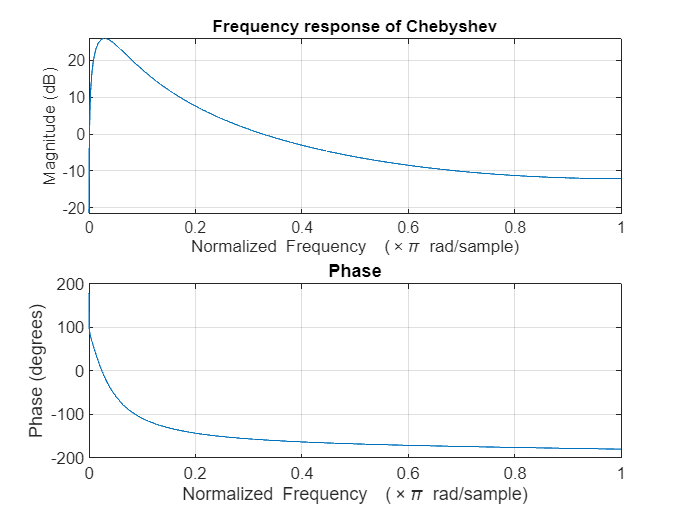


syms z n

% Extract coefficients directly from the transfer function
[numerator, denominator] = tfdata(cheby, 'v');

[h,t]=impz(numerator,denominator);
figure;
freqz(h, 1, 44100);
title('Frequency response of Chebyshev');

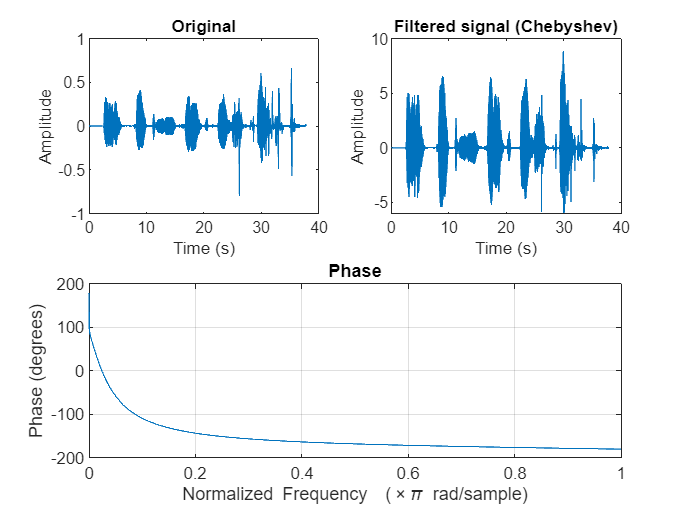


filteredSignal = conv(inputSignal,h);

subplot(2,2,1);
t = (0:length(inputSignal)-1) / Fs;
plot(t, inputSignal);
title('Original');
xlabel('Time (s)');
ylabel('Amplitude');
t = (0:length(filteredSignal)-1) / Fs; % Time vector

subplot(2,2,2);
plot(t, filteredSignal);
title('Filtered signal (Chebyshev)');
xlabel('Time (s)');
ylabel('Amplitude');

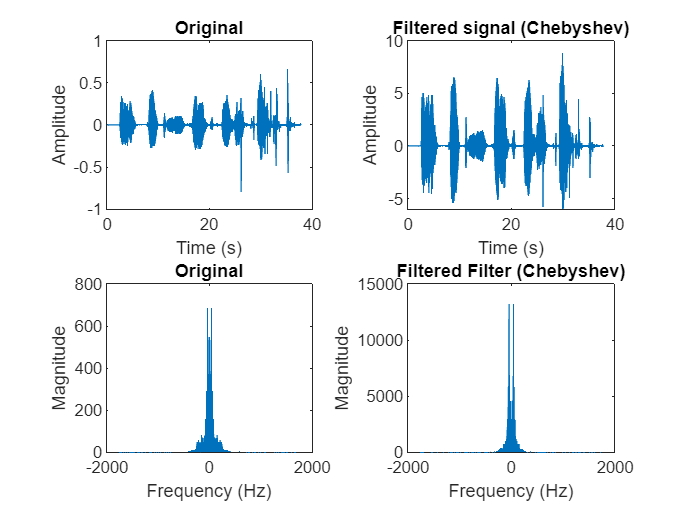


n = length(inputSignal);  % Set n based on the length of the signal
y = fft(inputSignal, n);
m = abs(y);
f = (0:length(y)-1) * Fs / length(y);
Y = fftshift(m);
fshift = (-n/2:n/2-1) * (Fs/n);

% Filtered
nf = length(filteredSignal);  % Set n based on the length of the signal
yf = fft(filteredSignal, nf);
mf = abs(yf);
ff = (0:length(yf)-1) *Fs / length(yf);
Yf = fftshift(mf);
fshiftf = (-nf/2:nf/2-1) * (Fs/nf);

subplot(2,2,3);
plot(fshift, Y);
title('Original');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(2,2,4);
plot(fshiftf, Yf);
title('Filtered Filter (Chebyshev)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');